# Bespoke Noiuse Generator

required_SNR_dB = 5; % Desired SNR in dB [dB].
required_SNR_linear = 10^(required_SNR_dB / 10); % [linear]

baseline_matrix_complex = active_inputdata; % [complex]
baseline_matrix_dB = active_slices_range_doppler; % [dB]

% Convert dB to linear for baseline_matrix
baseline_matrix_linear = cell(1, length(baseline_matrix_dB));
for i = 1:length(baseline_matrix_dB)
    baseline_matrix_linear{i} = 10.^(baseline_matrix_dB{i} / 20); % Convert dB to linear
end

% Calculate the average signal power for all elements
signalPower_linear = mean(cellfun(@(x) max(abs(x(:))), baseline_matrix_linear));

% Calculate noise power required to achieve the desired SNR
noisePower_linear = signalPower_linear / required_SNR_linear;

% Generate noise matrix with the calculated noise power
noise_complex = cell(1, length(baseline_matrix_complex));
for i = 1:length(baseline_matrix_complex)
    noise_complex{i} = sqrt(noisePower_linear/2) * ...
        (randn(size(baseline_matrix_complex{i})) + 1i .* randn(size(baseline_matrix_complex{i}))); % [complex]
end

% Add the original matrix to the new noise matrix.
noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
for i = 1:length(baseline_matrix_complex)
    noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex{i};
end

% Calculate SNR for the noisy matrix
noisy_SNR_linear = cellfun(@(x) max(abs(x(:))), noisyMatrix_complex) / noisePower_linear;
noisy_SNR_dB = 10 * log10(noisy_SNR_linear);
mean_noisy_SNR_dB = mean(noisy_SNR_dB);

disp(['Mean Noisy SNR (dB): ' num2str(mean_noisy_SNR_dB)]);

Mean Noisy SNR (dB): 2.7568



% Calculate SNR for the baseline matrix
baseline_SNR_linear = cellfun(@(x) max(abs(x(:))), baseline_matrix_complex) / noisePower_linear;
baseline_SNR_dB = 10 * log10(baseline_SNR_linear);
mean_baseline_SNR_dB = mean(baseline_SNR_dB);

disp(['Mean Baseline SNR (dB): ' num2str(mean_baseline_SNR_dB)]);

Mean Baseline SNR (dB): 2.5856


disp(['Signal Power (linear): ' num2str(signalPower_linear)]);

Signal Power (linear): 213.7044


disp(['Calculated Noise Power: ' num2str(noisePower_linear)]);

Calculated Noise Power: 67.5793


disp(['Scaling Factor: ' num2str(sqrt(noisePower_linear/2))]);

Scaling Factor: 5.8129


% required_SNR_dB = 10; % Desired SNR in dB [dB].
% required_SNR_linear = 10^(required_SNR_dB / 10); % [linear]
% 
% baseline_matrix_complex = active_inputdata; % [complex]
% baseline_matrix_linear = active_slices_range_doppler; % [linear]
% 
% signalPower_linear = zeros(1, length(baseline_matrix_linear)); % [linear]
% 
% % Calculate signal power for each element
% for i = 1:length(baseline_matrix_linear)
%     signalPower_linear(i) = max(abs(baseline_matrix_linear{i}(:))); % Use max magnitude
% end
% 
% 
% % Calculate noise power for each element
% noisePower_linear = signalPower_linear / required_SNR_linear; % [linear]
% 
% % Generate a noise matrix for each element
% noise_complex = cell(1, length(baseline_matrix_complex));
% for i = 1:length(baseline_matrix_complex)
%     % Use sqrt(noisePower_linear(i)/2) for complex noise
%     noise_complex{i} = sqrt(noisePower_linear(i)/2) * ...
%         (randn(size(baseline_matrix_complex{i})) + 1i .* randn(size(baseline_matrix_complex{i}))); % [complex]
% end
% 
% % Add the original matrix to the new noise matrix.
% noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
% for i = 1:length(baseline_matrix_complex)
%     noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex{i};
% end



% %%%%%%%%%
% required_SNR_dB = 20; % Desired SNR in dB [dB].
% required_SNR_linear = (10^(required_SNR_dB / 10)); % [linear]
% 
% baseline_matrix_complex = active_inputdata; % [complex]
% baseline_matrix_linear = active_slices_range_doppler_abs; % [linear]
% 
% signalPower_linear = zeros(1, length(baseline_matrix_linear));
% for i = 1:length(baseline_matrix_linear)
%     signalPower_linear(i) = mean(baseline_matrix_linear{i}(:)).^2; % [linear]
% end
% 
% % This calculates the noise power required to get to the desired SNR
% noisePower_linear = signalPower_linear / (10^(required_SNR_dB / 10));
% % noisePower_linear = signalPower_linear / required_SNR_linear; % [linear]
% %%%%%%%%%%%%%%%
% 
% 
% % Generate a noise matrix for each element
% noise_complex = cell(1, length(baseline_matrix_complex));
% for i = 1:length(baseline_matrix_complex)
%     noise_complex{i} = sqrt(noisePower_linear(i)/2) * ...
%         (randn(size(baseline_matrix_complex{i})) + 1i .* randn(size(baseline_matrix_complex{i}))); % [complex]
% end
% 
% % Add the original matrix to the new noise matrix.
% noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
% for i = 1:length(baseline_matrix_complex)
%     noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex{i};
% end

% %%%%%%%%%%%%%%%
% % This step makes a noise matrix that is the right power level and dimension.
% noise_complex = sqrt(noisePower_linear/2)...
%     .* (randn(size(noisePower_linear)) + 1i .* randn(size(noisePower_linear))); % [complex]
% noise_linear = abs(noise_complex); % [linear]
% noise_dB = 20*log10(abs(noise_complex)); % [dB]
% % Add the original matrix to the new noise matrix. 
% % Hopefully achieving the new desired SNR
% noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
% for i = 1:length(baseline_matrix_complex)
%     noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex(i);
% end % [complex]

### Use slice_SNR to process the noisyMatrix

% noisyMatrix_complex = inputstructure.range_doppler_slices;
% User defined ROI indices
active_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
active_roi_indices_cols = 65:99;   % input to slice_SNR func to calculate noise of roi
noisy_active_signal=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise_abs=zeros(1,length(noisyMatrix_complex)); % absolute mean noise (not dB) once func populates
noisy_active_SNR=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_slices_range_doppler = createArrays(length(noisyMatrix_complex), size(noisyMatrix_complex{1,1})); % [dB] once func populates
noisy_active_slices_range_doppler_abs = createArrays(length(noisyMatrix_complex), size(noisyMatrix_complex{1,1})); % absolute not dB, once func populates
noisy_active_signal_idx = zeros(1,length(noisyMatrix_complex));

for i=1:length(noisyMatrix_complex)
    [noisy_active_signal(i),...
        noisy_active_noise(i),...
        noisy_active_SNR(i),...
        noisy_active_slices_range_doppler{i},...
        noisy_active_signal_idx(i),...
        noisy_active_noise_abs(i),...
        noisy_active_slices_range_doppler_abs{i}]=slice_SNR(noisyMatrix_complex{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end   

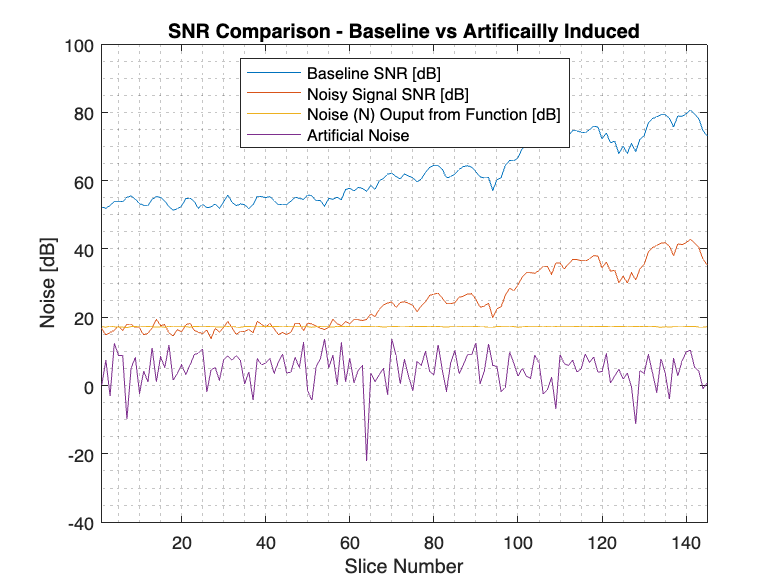

figure
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_noise), noisy_active_noise, ...
    1:length(noise_dB), noise_dB)
legend( 'Baseline SNR [dB]', 'Noisy Signal SNR [dB]', ...
    'Noise (N) Ouput from Function [dB]', 'Artificial Noise',...
    'location', 'north')
grid minor
title('SNR Comparison - Baseline vs Artificailly Induced');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])

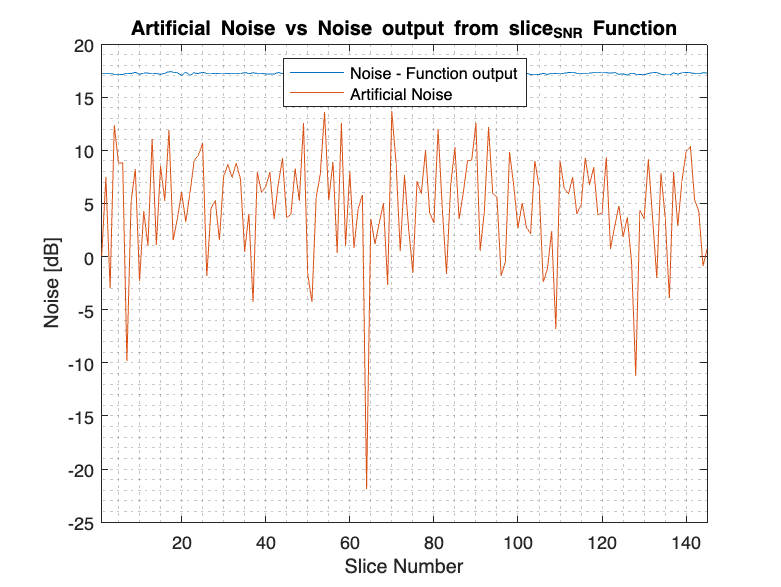


figure
plot(1:length(noisy_active_noise), noisy_active_noise, ...
    1:length(noise_dB), noise_dB)
legend('Noise - Function output', 'Artificial Noise',...
    'location', 'north')
grid minor
title('Artificial Noise vs Noise output from slice_SNR Function');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])

#### Calculating Metrics for Comparison - Min, Mean & Max

mean_active_SNR_dB = mean(active_SNR) % mean mean of the baseline SNR [dB]

mean_active_SNR_dB = 62.2783

mean_noisy_active_SNR_dB = mean(noisy_active_SNR) % mean of the noise SNR [dB]

mean_noisy_active_SNR_dB = 24.8695

mean_delta = -(mean_active_SNR_dB - mean_noisy_active_SNR_dB) % - to show reduction [dB]

mean_delta = -37.4089

#### Plot Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

Moving the Noisy SNR signal to have a mean = 0dB

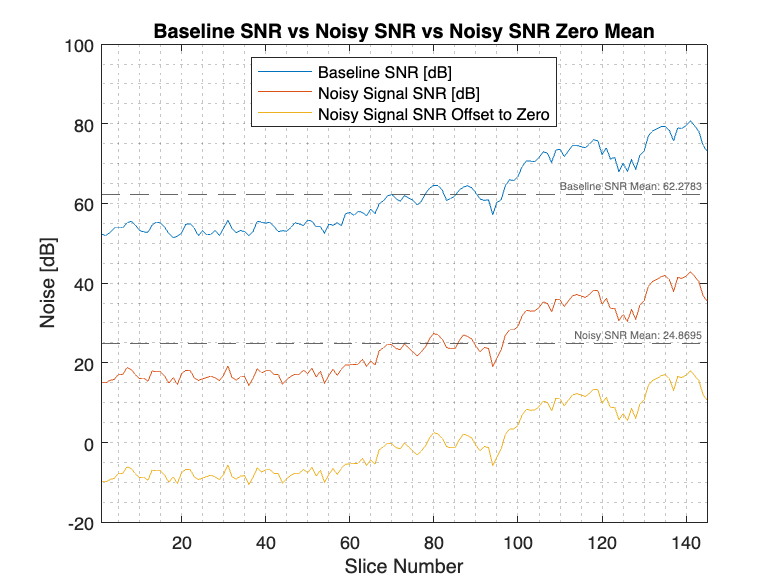

noisy_active_SNR_dB_zeroed = noisy_active_SNR - mean_noisy_active_SNR_dB; % [dB]
figure
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_SNR_dB_zeroed), noisy_active_SNR_dB_zeroed)
yline(mean_active_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(mean_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
yline(mean_noisy_active_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(mean_noisy_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', '', '', ...
    'location', 'best')
grid minor
title('Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(noisy_active_SNR)])